# Signal Processing Fundamentals

## 1. Signal Generation and Common Signal Analysis.

This section introduces generating and analyzing signals in the time domain.

Run each section with **Ctrl+Enter** (Run Section).

### 1.1. Exercise: Continuous Time to Samples.

A digital signal is a list of samples taken every $ T_s = 1/f_s $ seconds, where $ f_s $ is the **sampling rate**. By the Nyquist criterion, $ f_s $ must exceed **twice** the highest frequency present in the signal. Design the signal where the maximum frequency is `500 Hz` and time taken is 2 seconds.

% sampling rate (Hz)
fs = 1000;
% sample period (s)
Ts = 1/fs;
% 2 seconds of time stamps, as a column vector
t  = (0:Ts:2-Ts)';
% number of samples
N  = numel(t);

### 1.2. Exercise: Generate a Test Signal.

Design a signal where the frequency is 5 Hz component and the amplitude is 1. $ x(t) = \sin(2\pi \cdot 5t)$.

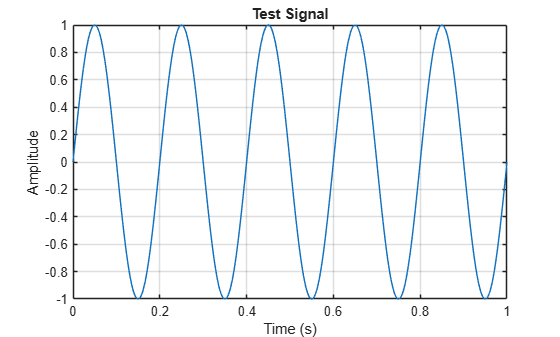

% Amplitude
a1 = 1;
% Frequency
f1 = 5;
% Create a signal: 5 Hz & Amplitude 1
x1 = a1*sin(2*pi*f1*t);
% Plot time-domain waveform and label axes for readability
plot(t, x1);
xlim([0 1]);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Test Signal');

Now lets combine our test signal with another signal with frequency 40 Hz and  amplitude 0.5, where the equation is $ x(t) = \sin(2\pi \cdot 5t) + 0.5\sin(2\pi \cdot 40t) $.

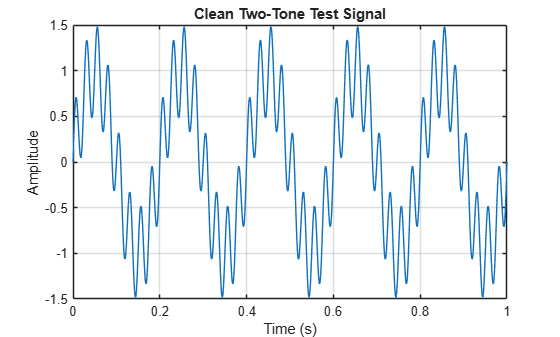

% Amplitude
a2 = 0.5;
% Frequency
f2 = 40;
% Create a clean two-tone signal: 5 Hz and 40 Hz components
xClean = x1 + a2*sin(2*pi*f2*t);
% Plot time-domain waveform and label axes for readability
plot(t, xClean);
xlim([0 1]);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Clean Two-Tone Test Signal');

### 1.3. Exercise: Add Measurement Noise.

Now, lets add additive white Gaussian noise (AWGN) into our test signal. AWGN is drawn from a normal distribution. `rng(0)` makes the result reproducible.

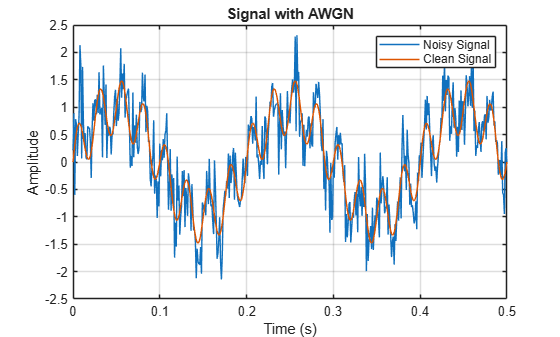

% Reproducible AWGN added to the clean signal, then plot comparison
rng(0);
% Noise standard deviation set to 0.4
noise  = 0.4*randn(N, 1);
% Add Noise into the Test Signal
xNoisy = xClean + noise;
% Plot noisy and clean traces together
plot(t, xNoisy);
hold on;
plot(t, xClean);
hold off;
% Zoom into the first 0.5 seconds for clarity
xlim([0 0.5]);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend('Noisy Signal', 'Clean Signal');
title('Signal with AWGN');

## 2. Spectral Analysis with the Signal Analyzer App.

The time-domain view shows *when* things happen; the frequency-domain view shows *what frequencies* are present and how strong they are.

### 2.1. Where is Signal Analyzer App?

On your MATLAB tabs at the top-left, select the tab **APPS**. 

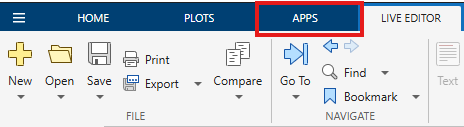

In the **APPS** tab, go to the **APPS** section and click on the drop down button.

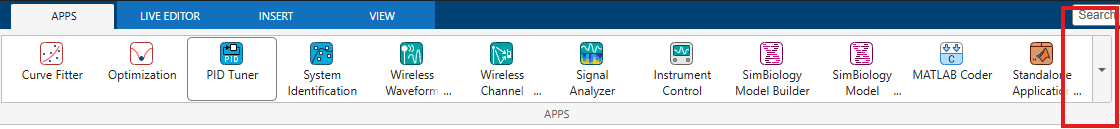

Then under the sub-section **Signal Processing and Audio**, search the **Signal Analyzer** app.

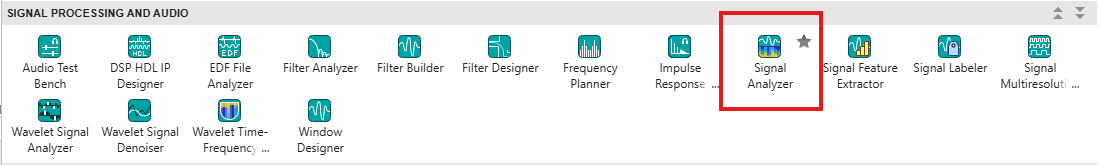

### 2.2. Inserting Data.

First we need to select our data to analysis.

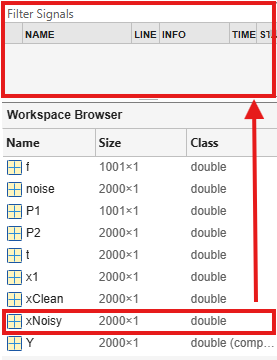

In the Signal Analyzer, drag `xNoisy` from the Workspace Browser to the Filter Signals Section.

Tick on xNoisy to see the results. By default the Signal Analyzer views the signal in time-domain.

### 2.3. Display Spectrum.

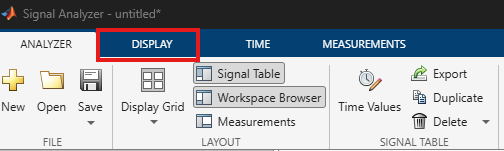

Now we want to see the spectrum of our signal. Click on **Display**.

Then under the **Views** section, click on the **Spectrum** button.

You can click on **Time** if you wish to remove it from the results.

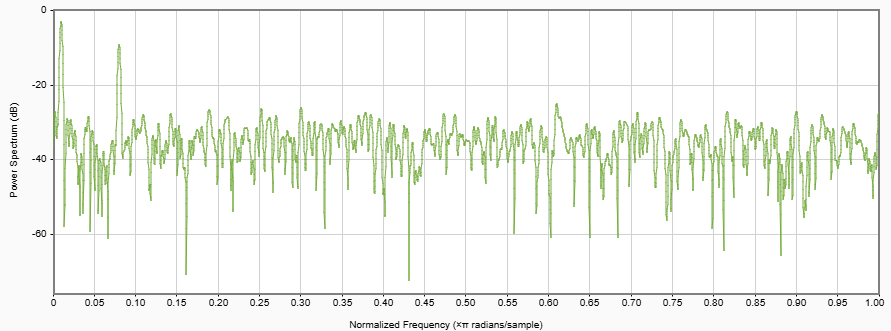

By default our spectrum result is in dB. Lets configure our spectrum result.

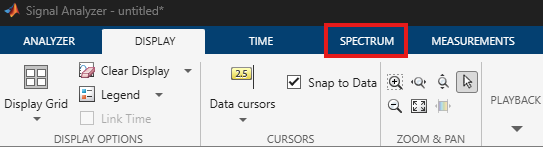

Click on the **Spectrum** Tab.

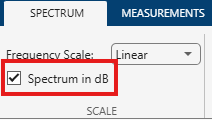

Spectrum in dB is ticked by default. Lets untick it and see our new graph result.

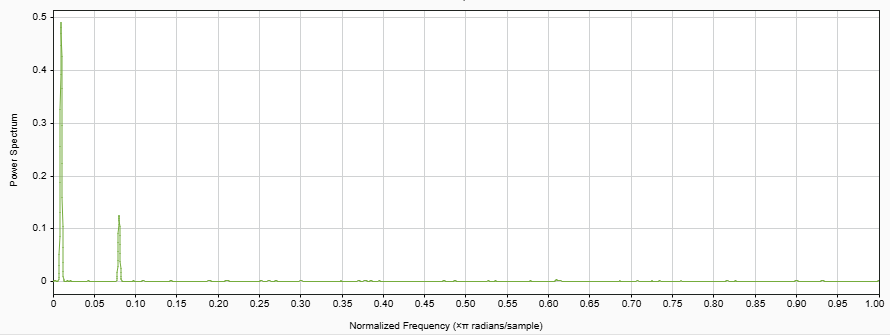

Now we can clearly see our peaks.

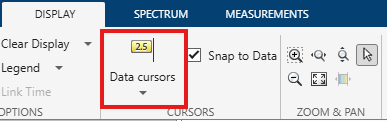

To get a more precise result, go to the **Display** tab. Then under the **Cursors** Section. Click on **Data Cursors**.

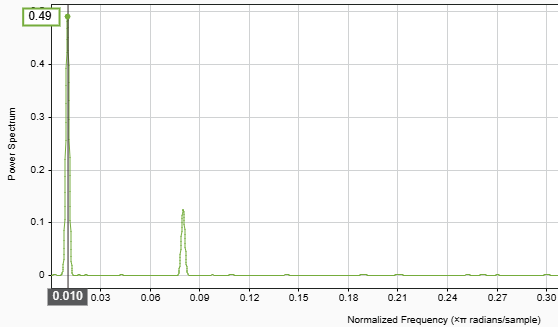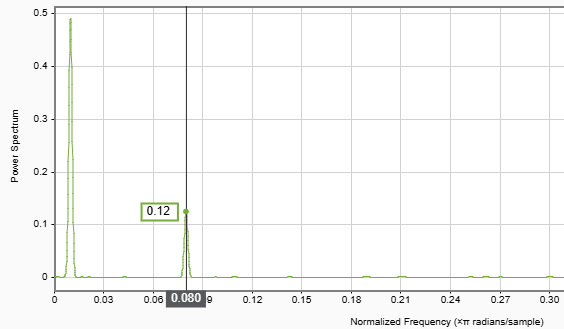

Drag your data cursor to the first peak, then the second one.

### 2.4. Result Analysis.

Since we know that our signal was two signals added at frequency 5 Hz and 40 Hz, we can compare the results of the Signal Analyzer.

peakFirst = 0.010 * fs/2

peakFirst = 5

peakSecond = 0.080 * fs/2

Our first and second peak correspond to our known signal's peaks.

## 3. Filter Design with the Filter Designer.

Filtering keeps the frequencies you want and rejects the ones you do not.

Now that you are familiar with apps. Find the **Filter Designer** under **Signal Processing and Audio**.

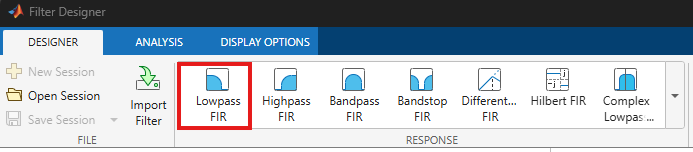

As you can see in the drop down list under response, there are many filters. Today, we will focus on the Lowpass FIR.

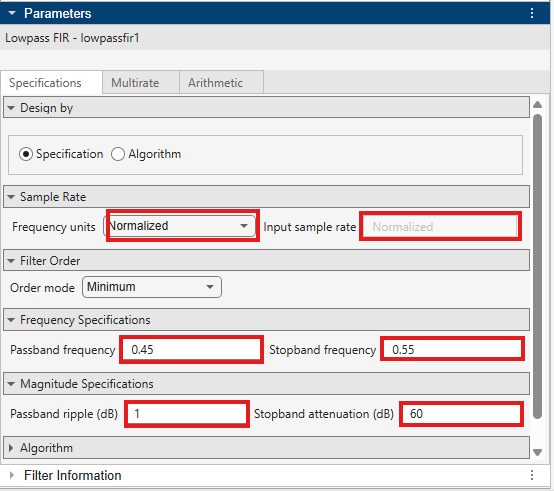

- Input sample rate to the frequency sampling.

- Change the passband frequency to 10 Hz, this keep everything below 10 Hz.

- Change the stopband frequency to 30 Hz, this reject everything above 30 Hz.

- Change the passband ripple to 0.5.

- Change the stopband attenuation to 60 dB for suppression in the stopband.

Then **export** to MATLAB workspace as a **digital filter object**. Using the code below see how the filter you designed works.

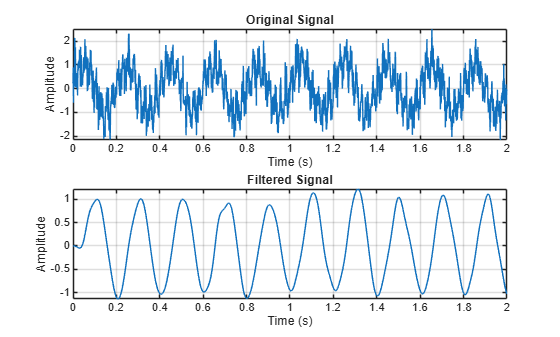

% Low Pass Filter
lowfiltsignal = filter(lowpassfir1, xNoisy);

% Plot Original & Filtered Signal use subplots
subplot(2,1,1);
plot(t,xNoisy);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t,lowfiltsignal);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

## 4. Building a Simulink Signal Processing Model

In this module you will build the model by hand from the Library Browser.

Create a blank model (**HOME > New > Simulink Model**), open the **Library Browser**, and drag in these blocks. This is a **discrete dynamic system**: every block runs once per sample tick.

Is your model working as intended?